# Interactive TinyMPC Example in MATLAB

We demonstrate an interactive workflow in MATLAB with TinyMPC where you can generate C code and interact with it via MATLAB. This example uses a cartpole linearized model.

Restart the kernel if something breaks.

**PLEASE CHANGE** **tinympc_matlab_dir** **TO YOUR ABSOLUTE PATH**

tinympc_matlab_dir = '/Users/elakhyanedumaran/Documents/Research/Tinympc_matlab_wrapper/'; % Your absolute path to the tinympc-matlab directory
tinympc_dir = fullfile(tinympc_matlab_dir,'tinympc','TinyMPC'); % Path to the TinyMPC directory (C code)
addpath(tinympc_matlab_dir);

Define the class.

prob = TinyMPC();

Compile the original TinyMPC code to get a generic shared/dynamic library

prob.compile_lib(tinympc_dir);  % Compile the library

CMake Deprecation Warning at CMakeLists.txt:1 (cmake_minimum_required):
  Compatibility with CMake < 3.5 will be removed from a future version of
  CMake.

  Update the VERSION argument <min> value or use a ...<max> suffix to tell
  CMake that the project does not need compatibility with older versions.


-- The CXX compiler identification is AppleClang 15.0.0.15000040
-- Detecting CXX compiler ABI info
-- Detecting CXX compiler ABI info - done
-- Check for working CXX compiler: /Applications/Xcode.app/Contents/Developer/Toolchains/XcodeDefault.xctoolchain/usr/bin/c++ - skipped
-- Detecting CXX compile features
-- Detecting CXX compile features - done
-- Configuring done (1.4s)
-- Generating done (0.0s)
-- Build files have been written to: /Users/elakhyanedumaran/Documents/Research/Tinympc_matlab_wrapper/tinympc/TinyMPC/build
[  6%] Building CXX object src/tinympc/CMakeFiles/tinympc.dir/admm.cpp.o
[ 12%] Building CXX object src/tinympc/CMakeFiles/tinympc.dir/codegen.cpp.o
/Users/elakhy

Load the generic shared/dynamic library

lib_dir = fullfile(tinympc_dir,'/build/src/tinympc/libtinympcShared.dylib');
generic_header = fullfile(tinympc_matlab_dir,'/matlab_wrapper/codegen.hpp')

generic_header = '/Users/elakhyanedumaran/Documents/Research/Tinympc_matlab_wrapper/matlab_wrapper/codegen.hpp'

prob = prob.load_lib(lib_dir,generic_header);  % Load the library

libtinympcShared loaded successfully


Problem data includes cartpole LTI model, cost weights, constraints and settings. All matrices are in row-major order and types are double and integer

n = 4; % state dimension: x, xdot, theta, thetadot
m = 1; % force dimension: F
N = 10; % horizon
A = [1.0, 0.0, 0.0, 0.0, 0.01, 1.0, 0.0, 0.0, 2.2330083403300767e-5, 0.004466210576510177, 1.0002605176397052, 0.05210579005928538, 7.443037974683548e-8, 2.2330083403300767e-5, 0.01000086835443038, 1.0002605176397052]; % A matrix in row-major order
B = [7.468368562730335e-5, 0.014936765390161838, 3.79763323185387e-5, 0.007595596218554721]; % B matrix in row-major order
Q = [10, 1, 10, 1];  % Q matrix is just diagonal in row-major order
R = 1; % R matrix is just diagonal in row-major order
rho = 0.1; % ADMM penalty parameter

x_min = repmat(-5, 1, n * N); % state constraints
x_max = repmat(5, 1, n * N); % state constraints
u_min = repmat(-5, 1, m * (N - 1)); % force constraints
u_max = repmat(5, 1, m * (N - 1));% force constraints
abs_pri_tol = 0.001; %  absolute primal tolerance
abs_dual_tol = 0.001; % absolute dual tolerance
max_iter = 100; % maximum number of iterations
check_termination = 1; % whether to check termination and period

% Setup problem data
prob = prob.setup(n, m, N, A, B, Q, R, x_min, x_max, u_min, u_max, 'rho', rho, 'abs_pri_tol',abs_pri_tol, 'abs_dual_tol', abs_dual_tol, 'max_iter',max_iter, 'check_termination',check_termination);

After we define the problem, we generate the tailored code with the above data.

Here, we compile it for this interactive MATLAB script but you can use it directly for your applications/systems.

output_dir = fullfile(tinympc_matlab_dir,'generated_code'); %Path to the generated code
prob.tiny_codegen(tinympc_dir, output_dir);

A = [        1,      0.01, 2.233e-05, 7.443e-08]
[        0,         1,  0.004466, 2.233e-05]
[        0,         0,         1,      0.01]
[        0,         0,   0.05211,         1]
B = [7.468e-05]
[  0.01494]
[3.798e-05]
[ 0.007596]
Q = [10.1,    0,    0,    0]
[   0,  1.1,    0,    0]
[   0,    0, 10.1,    0]
[   0,    0,    0,  1.1]
R = [1.1]
rho = 0.1
Kinf converged after 476 iterations
Precomputing finished
Kinf = [-2.912, -4.817,  44.35,  19.72]
Pinf = [     1671,      1319,     -6761,     -3032]
[     1319,      1485,     -8119,     -3644]
[    -6761,     -8119,  5.08e+04, 2.258e+04]
[    -3032,     -3644, 2.258e+04,  1.01e+04]
Quu_inv = [0.8397]
AmBKt = [        1,    0.0435, 0.0001106,   0.02212]
[  0.01036,     1.072, 0.0001829,   0.03659]
[ -0.00329,    -0.658,    0.9986,   -0.2848]
[-0.001472,   -0.2945,  0.009252,    0.8505]
coeff_d2p = [ 1.162e-06]
[ 1.818e-06]
[-1.132e-05]
[-5.079e-06]


prob.compile_lib(output_dir);  % Compile the library

CMake Deprecation Warning at CMakeLists.txt:5 (cmake_minimum_required):
  Compatibility with CMake < 3.5 will be removed from a future version of
  CMake.

  Update the VERSION argument <min> value or use a ...<max> suffix to tell
  CMake that the project does not need compatibility with older versions.


-- The CXX compiler identification is AppleClang 15.0.0.15000040
-- Detecting CXX compiler ABI info
-- Detecting CXX compiler ABI info - done
-- Check for working CXX compiler: /Applications/Xcode.app/Contents/Developer/Toolchains/XcodeDefault.xctoolchain/usr/bin/c++ - skipped
-- Detecting CXX compile features
-- Detecting CXX compile features - done
-- Configuring done (0.9s)
-- Generating done (0.0s)
-- Build files have been written to: /Users/elakhyanedumaran/Documents/Research/Tinympc_matlab_wrapper/generated_code/build
[ 11%] Building CXX object tinympc/CMakeFiles/tinympc.dir/admm.cpp.o
[ 22%] Linking CXX static library libtinympc.a
[ 22%] Built target tinympc
[ 33%] Building CXX

prob.unload_lib('libtinympcShared')

libtinympcShared unloaded successfully


Load the compiled shared/dynamic library

compiled_lib_dir = fullfile(output_dir,'/build/tinympc/libtinympcShared.dylib');
compiled_header = fullfile(tinympc_matlab_dir,'/matlab_wrapper/wrapper.hpp')

compiled_header = '/Users/elakhyanedumaran/Documents/Research/Tinympc_matlab_wrapper/matlab_wrapper/wrapper.hpp'

prob = prob.load_lib(compiled_lib_dir,compiled_header);

libtinympcShared loaded successfully


Run the interactive MPC example which calls the generated code.

Nsim = 300;
Anp = single(reshape(A, [n, n]));
Bnp = single(reshape(B, [n, m]));
x_all = {}; % List of all stored states
x0 = single([0.0; 0; 0.1; 0]); % Initial state
x_noise = x0.';

for k = 1:Nsim
    
    % 1. Set initial state from measurement    
    verbose_int = int32(0);
    prob.set_x0(x_noise, verbose_int); % Set initial state to C code
    
    % 2. Set the reference state if needed 
    
    % 3. Solve the problem
    prob.solve(verbose_int); % Call the solve in C code
    
    % 4. Get the control input
    u_soln = prob.get_u(verbose_int); % Get the control input from C code
    
    % 5. Simulate the dynamics    
    x1 = Anp * x0 + Bnp * u_soln(:, 1);

    x0 = single(x1);
    noise = 0.01 * randn(n, 1);
    x_noise = single(x1) + noise;
    
    x1 = x1(:).';
    x_noise = x_noise.';
    
    x_all{end + 1} = x1;
end
prob.unload_lib('libtinympcShared')

libtinympcShared unloaded successfully


Cartpole visualization

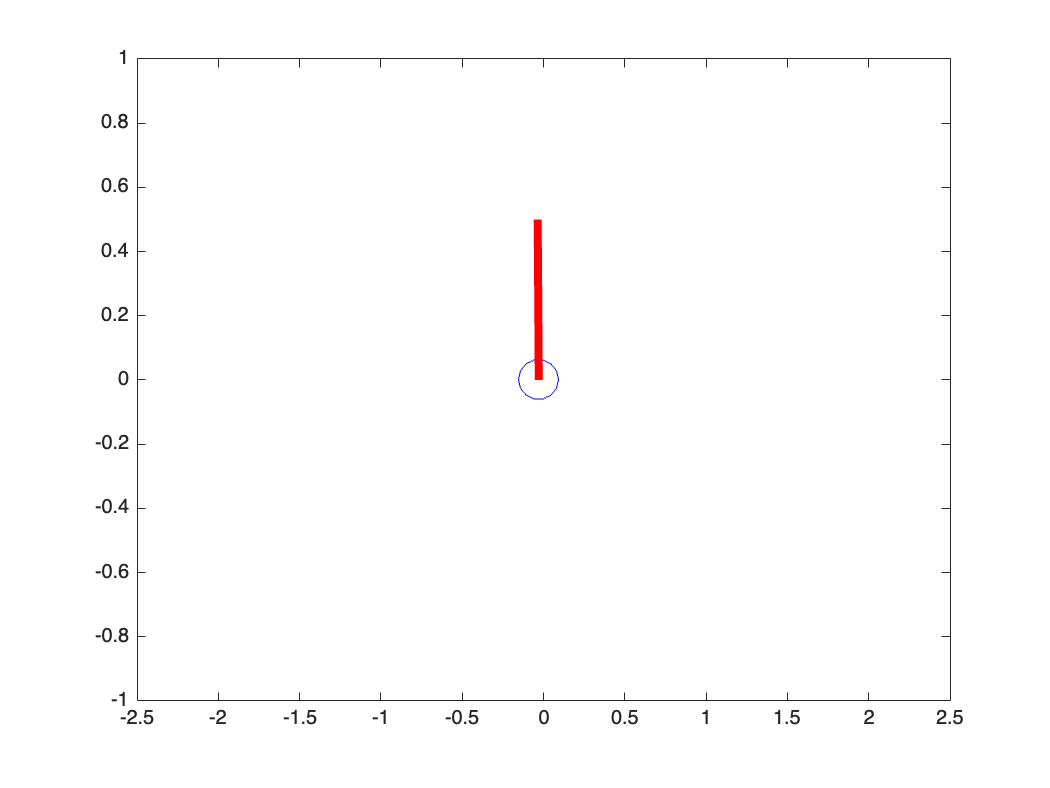

% Initialize cartpole visualization
figure;
xlim([-2.5, 2.5]);
ylim([-1, 1]);
cart = plot(NaN, NaN, 'bo', 'MarkerSize', 20);
hold on;
pole = plot(NaN, NaN, 'r-', 'LineWidth', 4);

init(cart,pole);
xlim([-2.5, 2.5]);
ylim([-1, 1]);
for frame = 1:Nsim
    update(frame,x_all,cart,pole);
    pause(0.01);
    F(frame) = getframe(gcf);
end

Save the animation

v = VideoWriter('cartpole_animation.mp4', 'MPEG-4');
open(v);
writeVideo(v, F);
close(v);

function init(cart,pole)
    set(cart, 'XData', []);
    set(cart, 'YData', []);
    set(pole, 'XData', []);
    set(pole, 'YData', []);
end

function update(frame,x_all,cart,pole)
    x_t_all = x_all.';
    x = x_t_all(frame, :);
    x(1);
    x_1 = x{1};
    % Update cart position
    set(cart, 'XData', x_1(1), 'YData', 0);
    
    % Update pole position
    set(pole, 'XData', [x_1(1), x_1(1) - 0.5 * sin(x_1(3))], 'YData', [0, 0.5 * cos(x_1(3))]);
    
    drawnow;
end

After testing MPC procedure with the generated code, you can deploy it to your applications/systems. Stay tuned for Teensy and STM32 deployment tutorials.